.Align spikes to lap

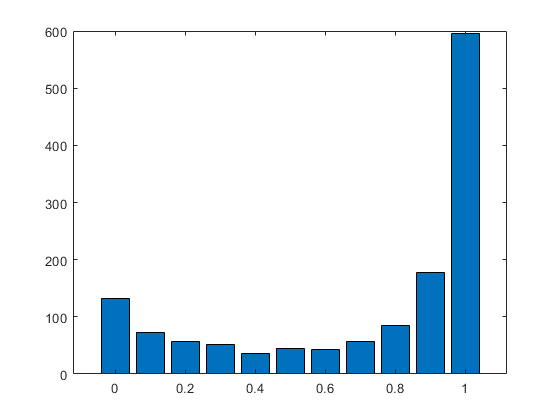


%% Hyperparameters setting
iscell=lap(1).iscell(:,2);
c=[0:0.1:1];

figure;
bar(c,hist(iscell,c));

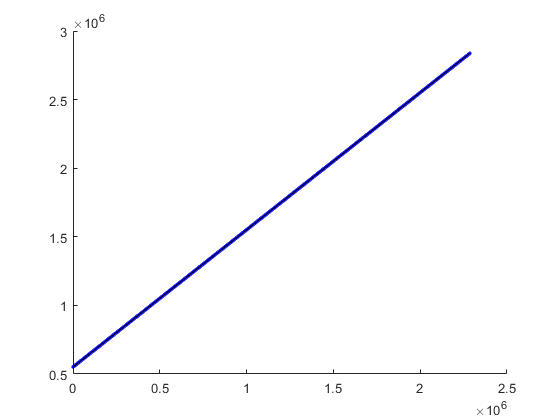


index_cell=find(iscell>=0.7);
num_cell=numel(index_cell);
num_lap=numel(lap);

cutoff_speed=2;

position_edge=0:2:320;% H322


% sigma=2;
% xk=[-3*sigma:3*sigma];
% kernel=exp(-xk.^2/2/sigma^2);
% kernel=kernel/sum(kernel);
% for i = 1:num_lap
%     lap(i).spk_smooth = filter(kernel,1,lap(i).spks,[],2);
% end

% transfer VR time into arduino time
t_unity=0;
t_arduino=0;

for i=1:(num_lap-1)
    t_sync=lap(i).t_sync;
    t_sync_arduino=lap(i).t_sync_arduino;
    num_t=numel(t_sync);
    t_unity((end+1):(end+num_t))=t_sync;
    t_arduino((end+1):(end+num_t))=t_sync_arduino;
end

t_unity(1)=[]; t_arduino(1)=[];
parameter=polyfit(t_unity,t_arduino,1);

figure; hold on;
plot(t_unity,t_arduino,'.b');
plot(t_unity,parameter(2)+parameter(1)*t_unity,'-k');

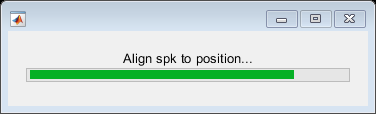


h = waitbar(0,'Align spk to position...');

for i=1:numel(lap)-1
    waitbar(i/num_lap,h);
    lap(i).t_position_arduino=round(parameter(2)+parameter(1)*lap(i).t_position);
    spk_interp=interp1(lap(i).t_sync_arduino_2p,lap(i).spks(index_cell,:)',lap(i).t_position_arduino','linear','extrap');
    speed_VR=diff(lap(i).position);
    index_nonzero=find(speed_VR>1e-3);
    index_start=index_nonzero(1);
    lap(i).spk_interp=spk_interp';
    lap(i).index_run=find((lap(i).speed(index_start:end))>cutoff_speed)+index_start-1;
    lap(i).spk_interp_run=lap(i).spk_interp(:,lap(i).index_run);
    position_run=lap(i).position(lap(i).index_run);
    bins=discretize(position_run,position_edge);
    lap(i).spk_interp_position=zeros(num_cell,numel(position_edge)-1);
    for j=1:numel(position_edge)-1
        index_bin=find(bins==j);
         if ~isempty(index_bin)             
            lap(i).spk_interp_position(:,j)=mean(lap(i).spk_interp_run(:,index_bin),2);
         else
%             lap(i).spk_interp_position(:,j)=mean([lap(i).spk_interp_run(:,find(bins==j-1 | bins==j+1))],2);
            d = 1;
            adj_idx = [];
            max_d = max(j-1, numel(position_edge)-j);  % 最大可扩展范围
            while isempty(adj_idx) && d <= max_d
                adj_idx = find(bins == j-d | bins == j+d);
                d = d + 1;
            end
            
            if ~isempty(adj_idx)
                lap(i).spk_interp_position(:, j) = mean(lap(i).spk_interp_run(:, adj_idx), 2, 'omitnan');
            else
                % 如果所有扩展都找不到（极端情况），则赋 0 或保持 NaN，视需求而定
                lap(i).spk_interp_position(:, j) = 0;   % 或 NaN
            end
        end 
    end
end

错误使用 matlab.internal.math.interp2
插值要求每个网格维度至少有两个采样点。

出错 interp1 (第 185 行)
        VqLite = matlab.internal.math.interp2(Xext,V,method,method,...

delete(h);


% spk to zscore
for i =1:numel(lap)-1
    spk_interp_position = lap(i).spk_interp_position;
    spk_interp_position_zscore = zscore(spk_interp_position');
    lap(i).spk_interp_position_zscore = spk_interp_position_zscore';
end

Sort cells based on spikes

clear spk_neuron spk_neuron_type spk_type spk_type_norm peak_position median_response max_median_response;
clear spk_neuron_odd spk_neuron_even spk_odd spk_even spk_norm_odd spk_norm_even peak_position_odd peak_position_even;

typenum = unique([lap.class]);
if length(typenum) ==2
    if typenum ==["position","position75"]
        typenum='position75';
        [lap.class] = deal("position75");
    elseif typenum ==["pattern","pattern75"]
        typenum='pattern75';
        [lap.class] = deal("pattern75");
    elseif typenum ==["origin","origin75"]
        typenum='origin75';
        [lap.class] = deal("origin75");
    end
end

if length(typenum) ==1
    if typenum == 'origin'
        trial_pool=[[0,1,3,2,0];
                    [0,2,3,1,0];];
        trial_name=["XACBX","XBCAX"];
    elseif typenum =='origin75'
        trial_pool=[[0,1,3,2,0];
                    [0,2,3,1,0];];
        trial_name=["XACBX","XBCAX"];
    elseif typenum =='position'
        trial_pool=[[23,21,20,22,20];
                    [23,22,20,21,20];
                    [20,21,23,22,20];
                    [20,22,23,21,20];
                    [20,21,20,22,23];
                    [20,22,20,21,23]];
        trial_name=["CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    elseif typenum == 'pattern75'
        trial_pool=[[13,11,10,12,10];
                    [13,12,10,11,10];
                    [10,11,13,12,10];
                    [10,12,13,11,10];
                    [10,11,10,12,13];
                    [10,12,10,11,13]];
        trial_name=["CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    elseif typenum == 'position75'
        trial_pool=[[23,21,20,22,20];
                    [23,22,20,21,20];
                    [20,21,23,22,20];
                    [20,22,23,21,20];
                    [20,21,20,22,23];
                    [20,22,20,21,23]];
        trial_name=["CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    elseif typenum == 'pre-pattern'
        trial_pool=[[30,30,31,32];
                    [30,30,32,31];
                    [30,31,32,30];
                    [30,32,31,30];
                    [30,31,30,32];
                    [30,32,30,31];
                    [31,32,30,30];
                    [32,31,30,30];
                    [31,30,32,30];
                    [32,30,31,30];
                    [31,30,30,32];
                    [32,30,30,31];
                    ];
        trial_name=["XXED","XXDE",'XEDX',"XDEX",'XEXD','XDXE','EDXX','DEXX','EXDX','DXEX','EXXD','DXXE'];
    else
        trial_pool=[[13,11,10,12,10];
                    [13,12,10,11,10];
                    [10,11,13,12,10];
                    [10,12,13,11,10];
                    [10,11,10,12,13];
                    [10,12,10,11,13]];
        trial_name=["CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    end
elseif length(typenum) == 2
    if typenum == ["origin","position"]
%       couple-->position
        trial_pool=[[0,1,3,2,0];
                    [0,2,3,1,0];
                    [23,21,20,22,20];
                    [23,22,20,21,20];
                    [20,21,23,22,20];
                    [20,22,23,21,20];
                    [20,21,20,22,23];
                    [20,22,20,21,23]];
        trial_name=["XACBX","XBCAX","CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    elseif typenum == ["origin","pattern"]
%         couple-->pattern
        trial_pool=[[0,1,3,2,0];
                    [0,2,3,1,0];
                    [13,11,10,12,10];
                    [13,12,10,11,10];
                    [10,11,13,12,10];
                    [10,12,13,11,10];
                    [10,11,10,12,13];
                    [10,12,10,11,13]];
        trial_name=["XACBX","XBCAX","CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    elseif typenum ==["pattern","patternNEW"]
        trial_pool=[[13,11,10,12,10];
                    [13,12,10,11,10];
                    [10,11,13,12,10];
                    [10,12,13,11,10];
                    [10,11,10,12,13];
                    [10,12,10,11,13];
                    [33,31,30,32,30];
                    [33,32,30,31,30];
                    [30,31,33,32,30];
                    [30,32,33,31,30];
                    [30,31,30,32,33];
                    [30,32,30,31,33]];
        trial_name=["CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC',"CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    elseif typenum ==["origin" ,"pre-pattern"] 
        trial_pool={[30,30,31,32];
                    [30,30,32,31];
                    [30,31,32,30];
                    [30,32,31,30];
                    [30,31,30,32];
                    [30,32,30,31];
                    [31,32,30,30];
                    [32,31,30,30];
                    [31,30,32,30];
                    [32,30,31,30];
                    [31,30,30,32];
                    [32,30,30,31];
                    [0,1,3,2,0];
                    [0,2,3,1,0]};
        trial_name=["XXED","XXDE",'XEDX',"XDEX",'XEXD','XDXE','EDXX','DEXX','EXDX','DXEX','EXXD','DXXE',"CAXBX","CBXAX"];
    elseif typenum ==['pre-pattern','origin'] 
        trial_pool={[30,30,31,32];
                    [30,30,32,31];
                    [30,31,32,30];
                    [30,32,31,30];
                    [30,31,30,32];
                    [30,32,30,31];
                    [31,32,30,30];
                    [32,31,30,30];
                    [31,30,32,30];
                    [32,30,31,30];
                    [31,30,30,32];
                    [32,30,30,31];
                    [0,1,3,2,0];
                    [0,2,3,1,0]};
        trial_name=["XXED","XXDE",'XEDX',"XDEX",'XEXD','XDXE','EDXX','DEXX','EXDX','DXEX','EXXD','DXXE',"CAXBX","CBXAX"];
    else
        %couple-->pattern
        trial_pool=[[13,11,10,12,10];
                    [13,12,10,11,10];
                    [10,11,13,12,10];
                    [10,12,13,11,10];
                    [10,11,10,12,13];
                    [10,12,10,11,13];
                    [23,21,20,22,20];
                    [23,22,20,21,20];
                    [20,21,23,22,20];
                    [20,22,23,21,20];
                    [20,21,20,22,23];
                    [20,22,20,21,23]];
        trial_name=["CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC',"CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    end
elseif length(typenum) == 3
    if typenum == ["origin","pattern","pattern75"]
%       couple-->pattern->pattern75
        trial_pool=[[0,1,3,2,0];
                    [0,2,3,1,0];
                    [13,11,10,12,10];
                    [13,12,10,11,10];
                    [10,11,13,12,10];
                    [10,12,13,11,10];
                    [10,11,10,12,13];
                    [10,12,10,11,13]];
        trial_name=["XACBX","XBCAX","CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    elseif typenum == ["origin","position","position75"]
        trial_pool=[[0,1,3,2,0];
                    [0,2,3,1,0];
                    [23,21,20,22,20];
                    [23,22,20,21,20];
                    [20,21,23,22,20];
                    [20,22,23,21,20];
                    [20,21,20,22,23];
                    [20,22,20,21,23]];
        trial_name=["XACBX","XBCAX","CAXBX","CBXAX",'XACBX',"XBCAX", 'XAXBC','XBXAC'];
    end
end

contain75 = contains(typenum,'75');

[n_type,n_cue]=size(trial_pool);

h = waitbar(0,'Sort trial types...');
for i=1:num_cell
    waitbar(i/num_cell,h);
    num_trialtype=zeros(1,n_type);
    num_trialtype_withoutreward=zeros(1,n_type);
    num_trialtype_false=zeros(1,n_type);
    num_trialtype_miss=zeros(1,n_type);
    F_num_trialtype = zeros(1,n_type);
    for j=1:(num_lap-1)
        spk_neuron(i).spk_position(j,:)=lap(j).spk_interp_position_zscore(i,:);
        spk_neuron(i).raw_spk_position(j,:) = lap(j).spk_interp_position(i,:);
        lap_type_use = lap(j).trial_style;
        for k=1:n_type
            if isequal(lap_type_use,trial_pool(k,:))
                if any(contain75)
                    if lap(j).Correct == 1
                        if isempty(lap(j).pos_reward)==1
                            num_trialtype_withoutreward(k)=num_trialtype_withoutreward(k)+1;
                            spk_neuron_type_noreward(i,k).lap_position(num_trialtype_withoutreward(k),:)=lap(j).spk_interp_position_zscore(i,:);
                            spk_neuron_type_noreward(i,k).raw_lap_position(num_trialtype_withoutreward(k),:)=lap(j).spk_interp_position(i,:);
                            index_lap_type_noreward(k).index(num_trialtype_withoutreward(k))=j;
%                             spk_neuron_type_try(i,k).lap_position(num_trialtype_withoutreward(k),:)=lap(j).spk_interp_position_zscore(i,:);
                        else
                            num_trialtype(k)=num_trialtype(k)+1;
                            spk_neuron_type(i,k).lap_position(num_trialtype(k),:)=lap(j).spk_interp_position_zscore(i,:);
                            spk_neuron_type(i,k).raw_lap_position(num_trialtype(k),:)=lap(j).spk_interp_position(i,:);
                            index_lap_type(k).index(num_trialtype(k))=j;
                        end
                     elseif lap(j).FalseAlarm == 1
                        num_trialtype_false(k)=num_trialtype_false(k)+1;
                        spk_neuron_type_false(i,k).lap_position(num_trialtype_false(k),:)=lap(j).spk_interp_position_zscore(i,:);
                        spk_neuron_type_false(i,k).raw_lap_position(num_trialtype_false(k),:)=lap(j).spk_interp_position(i,:);
                        index_lap_type_false(k).index(num_trialtype_false(k))=j;
                     elseif lap(j).Miss == 1
                        num_trialtype_miss(k)=num_trialtype_miss(k)+1;
                        spk_neuron_type_miss(i,k).lap_position(num_trialtype_miss(k),:)=lap(j).spk_interp_position_zscore(i,:);
                        spk_neuron_type_miss(i,k).raw_lap_position(num_trialtype_miss(k),:)=lap(j).spk_interp_position(i,:);
                        index_lap_type_miss(k).index(num_trialtype_miss(k))=j;
                    end
                else
                     if lap(j).Correct == 1
                        num_trialtype(k)=num_trialtype(k)+1;
                        spk_neuron_type(i,k).lap_position(num_trialtype(k),:)=lap(j).spk_interp_position_zscore(i,:);
                        spk_neuron_type(i,k).raw_lap_position(num_trialtype(k),:)=lap(j).spk_interp_position(i,:);
                        index_lap_type(k).index(num_trialtype(k))=j;
                     elseif lap(j).FalseAlarm == 1
                        num_trialtype_false(k)=num_trialtype_false(k)+1;
                        spk_neuron_type_false(i,k).lap_position(num_trialtype_false(k),:)=lap(j).spk_interp_position_zscore(i,:);
                        spk_neuron_type_false(i,k).raw_lap_position(num_trialtype_false(k),:)=lap(j).spk_interp_position(i,:);
                        index_lap_type_false(k).index(num_trialtype_false(k))=j;
                     elseif lap(j).Miss == 1
                        num_trialtype_miss(k)=num_trialtype_miss(k)+1;
                        spk_neuron_type_miss(i,k).lap_position(num_trialtype_miss(k),:)=lap(j).spk_interp_position_zscore(i,:);
                        spk_neuron_type_miss(i,k).raw_lap_position(num_trialtype_miss(k),:)=lap(j).spk_interp_position(i,:);
                        index_lap_type_miss(k).index(num_trialtype_miss(k))=j;
                     end
                end
            end
        end
    end
    
    for k=1:n_type
        %peak_response=max(spk_neuron_type(i,k).spk_position');
        %median_response(i,k)=median(peak_response);
        
        %median_response(i,k,:)=median(spk_neuron_type(i,k).spk_position);
        if num_trialtype(k)==0
            median_response(i,k,:) = zeros(0,160);
        else
            median_response(i,k,:)=SelectPercentile(spk_neuron_type(i,k).lap_position,50);
            peak_response(i,k)=max(median_response(i,k,:));
%         F_median_response(i,k,:)=SelectPercentile(F_spk_neuron_type(i,k).lap_position,50);
%         F_peak_response(i,k)=max(F_median_response(i,k,:));
        end
    end
    max_median_spk(i)=max(peak_response(i,:));
%     F_max_median_spk(i)=max(F_peak_response(i,:));
end
delete(h);

h = waitbar(0,'Sort even/odd trials...');

for i=1:num_cell
    waitbar(i/num_lap,h);
    for k=1:n_type
        if num_trialtype(k)>=1
            spk_neuron_odd(i,k).spk_position=spk_neuron_type(i,k).lap_position(1:2:end,:);
            spk_neuron_even(i,k).spk_position=spk_neuron_type(i,k).lap_position(2:2:end,:);
        else
            spk_neuron_odd(i,k).spk_position = zeros(1,160);
            spk_neuron_odd(i,k).spk_position = zeros(1,160);
        end
    end
%     for k=1:n_type
%         F_spk_neuron_odd(i,k).spk_position=F_spk_neuron_type(i,k).lap_position(1:2:end,:);
%         F_spk_neuron_even(i,k).spk_position=F_spk_neuron_type(i,k).lap_position(2:2:end,:);
%     end
end
delete(h);

c=[0:0.1:10];
%计算前250
top_use = 251;
top_num = min(top_use, length(max_median_spk));
top_values = maxk(max_median_spk, top_num);
min_in_top = 0;

cutoff_spk = min_in_top;
F_cutoff_spk=5; 
hist_peak=hist(max_median_spk,c);

figure;hold on;
bar(c,hist_peak);
plot([cutoff_spk+0.05,cutoff_spk+0.05],[0,max(hist_peak)],'--r','LineWidth',1.5);

h = waitbar(0,'Sort responsive neurons...');
index_responsive=find(max_median_spk>cutoff_spk);
% F_index_responsive=find(F_max_median_spk>F_cutoff_spk);

% if any(contain75)
%     if length(spk_neuron_type_noreward(1,:))<8
%          [spk_neuron_type_noreward(:,8).lap_position] = deal([]);
%          index_lap_type_noreward(8).index = [];
%     end
% end

for k=1:n_type
    waitbar(k/n_type,h);
    for i=1:numel(index_responsive)
        if k>length(index_lap_type)
            spk_type(k,i,:)=zeros(1,160);
            raw_spk_type(k,i,:) =zeros(1,160);
            spk_neuron_type_save(i,k).Correct = zeros(1,160);
            spk_neuron_type_save(i,k).FalseAlarm = zeros(1,160);
            spk_neuron_type_save(i,k).Miss = zeros(1,160);
            spk_even(k,i,:)=zeros(1,160);
            spk_odd(k,i,:)=zeros(1,160);
        else

            spk_neuron_type_save(i,k).Correct = spk_neuron_type(index_responsive(i),k).lap_position;
            use_spk_data = spk_neuron_type(index_responsive(i),k).lap_position;
            non_nan_rows = ~any(isnan(use_spk_data), 2);
            clean_spk_data = use_spk_data(non_nan_rows, :);
            spk_neuron_type(index_responsive(i),k).lap_position =clean_spk_data;
    
            if length(index_lap_type(k).index)>1
                spk_type(k,i,:)=mean(spk_neuron_type(index_responsive(i),k).lap_position);
            elseif length(index_lap_type(k).index)==1
                spk_type(k,i,:)=spk_neuron_type(index_responsive(i),k).lap_position;
            else
                spk_type(k,i,:)=zeros(1,160);
            end
    
    
            if num_trialtype_false(k) >=1
                use_spk_data_false = spk_neuron_type_false(index_responsive(i),k).lap_position;
                non_nan_rows_false = ~any(isnan(use_spk_data_false), 2);
                clean_spk_data_false = use_spk_data_false(non_nan_rows_false, :);
                spk_neuron_type_false(index_responsive(i),k).lap_position =clean_spk_data_false;
                spk_neuron_type_save(i,k).FalseAlarm = clean_spk_data_false;
            else
                spk_neuron_type_save(i,k).FalseAlarm = zeros(1,160);
            end
    
            
            if num_trialtype_miss(k)>=1
                use_spk_data_miss = spk_neuron_type_miss(index_responsive(i),k).lap_position;
                non_nan_rows_miss = ~any(isnan(use_spk_data_miss), 2);
                clean_spk_data_miss = use_spk_data_miss(non_nan_rows_miss, :);
                spk_neuron_type_miss(index_responsive(i),k).lap_position =clean_spk_data_miss;
                spk_neuron_type_save(i,k).Miss = clean_spk_data_miss;
            else
                spk_neuron_type_save(i,k).Miss = zeros(1,160);
            end
    
    
    
            spk_type_norm(k,i,:)=spk_type(k,i,:)/max(spk_type(k,i,:));
            peak_position(k,i)=find(spk_type(k,i,:)==max(spk_type(k,i,:)),1);
    
            use_spk_data = spk_neuron_type(index_responsive(i),k).raw_lap_position;
            non_nan_rows = ~any(isnan(use_spk_data), 2);
            clean_spk_data = use_spk_data(non_nan_rows, :);
            spk_neuron_type(index_responsive(i),k).raw_lap_position =clean_spk_data;
            
            if length(index_lap_type(k).index)>1
                raw_spk_type(k,i,:) = mean(spk_neuron_type(index_responsive(i),k).raw_lap_position);
            elseif length(index_lap_type(k).index)==1
                raw_spk_type(k,i,:) = spk_neuron_type(index_responsive(i),k).raw_lap_position;
            else
                raw_spk_type(k,i,:) =zeros(1,160);
            end
    
    %         use_spk_data = spk_neuron_type_false(index_responsive(i),k).lap_position;
    %         non_nan_rows = ~any(isnan(use_spk_data), 2);
    %         clean_spk_data = use_spk_data(non_nan_rows, :);
    %         spk_neuron_type_false(index_responsive(i),k).lap_position =clean_spk_data;
    % 
    %         if length(index_lap_type_false(k).index)>1
    %             spk_type_false(k,i,:)=mean(spk_neuron_type_false(index_responsive(i),k).lap_position);
    %         elseif length(index_lap_type_false(k).index)==1
    %             spk_type_false(k,i,:)=spk_neuron_type_false(index_responsive(i),k).lap_position;
    %         else
    %             spk_type_false(k,i,:)=zeros(1,160);
    %         end
            if any(contain75)
                if num_trialtype_withoutreward(k)>=1
                    use_spk_data = spk_neuron_type_noreward(index_responsive(i),k).lap_position;
                    non_nan_rows = ~any(isnan(use_spk_data), 2);
                    clean_spk_data = use_spk_data(non_nan_rows, :);
                    spk_neuron_type_noreward(index_responsive(i),k).lap_position =clean_spk_data;
                    spk_neuron_type_save(i,k).NoReward = clean_spk_data;
                else
                    spk_neuron_type_save(i,k).NoReward =zeros (1,160);
                    spk_neuron_type_noreward(index_responsive(i),k).lap_position = zeros(1,160);
                end
    
                if num_trialtype_withoutreward(k)>1
                    spk_type_no_reward(k,i,:)=mean(spk_neuron_type_noreward(index_responsive(i),k).lap_position);
                elseif num_trialtype_withoutreward(k)==1
                    spk_type_no_reward(k,i,:)=spk_neuron_type_noreward(index_responsive(i),k).lap_position;
                elseif num_trialtype_withoutreward(k)==0
                    spk_type_no_reward(k,i,:)=zeros(1,160);
                end
                
                if num_trialtype_withoutreward(k)>=1
                    use_spk_data = spk_neuron_type_noreward(index_responsive(i),k).raw_lap_position;
                    non_nan_rows = ~any(isnan(use_spk_data), 2);
                    clean_spk_data = use_spk_data(non_nan_rows, :);
                    spk_neuron_type_noreward(index_responsive(i),k).raw_lap_position =clean_spk_data;
                else
                    spk_neuron_type_noreward(index_responsive(i),k).raw_lap_position =zeros (1,160);
                end
    
                if num_trialtype_withoutreward(k)>1
                    raw_spk_type_no_reward(k,i,:) = mean(spk_neuron_type_noreward(index_responsive(i),k).raw_lap_position);
                elseif num_trialtype_withoutreward(k)==1
                    raw_spk_type_no_reward(k,i,:) = spk_neuron_type_noreward(index_responsive(i),k).raw_lap_position;
                elseif num_trialtype_withoutreward(k)==0
                    raw_spk_type_no_reward(k,i,:) = zeros(1,160);
                end
            end
    
            use_spk_data = spk_neuron_odd(index_responsive(i),k).spk_position;
            non_nan_rows = ~any(isnan(use_spk_data), 2);
            clean_spk_data = use_spk_data(non_nan_rows, :);
            spk_neuron_odd(index_responsive(i),k).spk_position =clean_spk_data;
            
            if length(index_lap_type(k).index)>1
                spk_odd(k,i,:)=mean(spk_neuron_odd(index_responsive(i),k).spk_position);
            elseif length(index_lap_type(k).index)==1
                spk_odd(k,i,:)=spk_neuron_odd(index_responsive(i),k).spk_position;
            else
                spk_odd(k,i,:)=zeros(1,160);
            end
    %         spk_odd(k,i,:)=mean(spk_neuron_odd(index_responsive(i),k).spk_position,1);
            spk_norm_odd(k,i,:)=spk_odd(k,i,:)/max(spk_odd(k,i,:));
            peak_position_odd(k,i)=find(spk_odd(k,i,:)==max(spk_odd(k,i,:)),1);
    %         
            use_spk_data = spk_neuron_even(index_responsive(i),k).spk_position;
            non_nan_rows = ~any(isnan(use_spk_data), 2);
            clean_spk_data = use_spk_data(non_nan_rows, :);
            spk_neuron_even(index_responsive(i),k).spk_position =clean_spk_data;
            
            if k>length(index_lap_type)
                spk_even(k,i,:)=zeros(1,160);
            else
                if length(index_lap_type(k).index)>1
                    spk_even(k,i,:)=mean(spk_neuron_even(index_responsive(i),k).spk_position);
                elseif length(index_lap_type(k).index)==1
                        spk_even(k,i,:)=zeros(1,160);
                else
                    spk_even(k,i,:)=zeros(1,160);
                end
        %         spk_even(k,i,:)=mean(spk_neuron_even(index_responsive(i),k).spk_position,1);
                spk_norm_even(k,i,:)=spk_even(k,i,:)/max(spk_even(k,i,:));
                peak_position_even(k,i)=find(spk_even(k,i,:)==max(spk_even(k,i,:)),1);
            end
    
    %     for j=1:numel(F_index_responsive)
    %         F_spk_type(k,j,:)=mean(F_spk_neuron_type(F_index_responsive(j),k).lap_position);
    %         F_spk_type_norm(k,j,:)=F_spk_type(k,j,:)/max(F_spk_type(k,j,:));
    %         F_peak_position(k,j)=find(F_spk_type(k,j,:)==max(F_spk_type(k,j,:)),1);
    % 
    %         F_spk_norm_odd(k,j,:)=F_spk_odd(k,j,:)/max(F_spk_odd(k,j,:));
    %         F_peak_position_odd(k,j)=find(F_spk_odd(k,j,:)==max(F_spk_odd(k,j,:)),1);
    %         
    %         F_spk_even(k,j,:)=mean(F_spk_neuron_even(F_index_responsive(j),k).spk_position,1);
    %         F_spk_norm_even(k,j,:)=F_spk_even(k,j,:)/max(F_spk_even(k,j,:));
    %         F_peak_position_even_test = find(F_spk_even(k,j,:)==max(F_spk_even(k,j,:)),1);
    % 
    %         if isempty(F_peak_position_even_test)==0
    %             F_peak_position_even(k,j)=F_peak_position_even_test;
    %         else 
    %             F_peak_position_even(k,j)=[NaN];
    %         end
        end
    end
end
delete(h);

place_separate = [0,36.4,60.4,96.4,120.4,156.4,180.4,216.4,240.4,276.4,300.4,320];
use_cell_number = numel(index_responsive);
firing_cell_number = zeros(n_type,length(place_separate)-1);
firing_cell_percent = zeros(n_type,length(place_separate)-1);
for p = 1:n_type
    if p <= length(index_lap_type)
        for q =1:(length(place_separate)-1)
            part_start = place_separate(q)/2;
            part_end = place_separate(q+1)/2;
            this_firing_cell_number = numel(find((part_start<=peak_position(p,:))&(part_end>=peak_position(p,:))));
            this_firing_cell_percent = this_firing_cell_number/use_cell_number;
            firing_cell_number(p,q) = this_firing_cell_number;
            firing_cell_percent(p,q) =this_firing_cell_percent;
        end
        cell(p).cell_number = firing_cell_number(p,:);
        cell(p).cell_percent = firing_cell_percent(p,:);
        cell(p).type = trial_pool(p,:);
    end
end
if any(contain75)
    raw_spk_type = [raw_spk_type;raw_spk_type_no_reward];
    for i = 1:length(raw_spk_type(:,1,1))
        for m =1:use_cell_number
            raw_firing_avg(i,m) = mean(raw_spk_type(i,m,:));
        end
    end
end


% save(save_file, 'lap','-v7.3');

all_save = struct();
all_save.type = typenum;
all_save.response_cell = index_responsive;
all_save.spk = spk_type;
all_save.raw_spk = raw_spk_type;
all_save.trial_type = trial_pool;
all_save.cell_number = firing_cell_number;
all_save.percent = firing_cell_percent;
all_save.peak_position = peak_position;

% 
% cell_file_name = sprintf('cell_number_%s_%s_%s.mat', number, trial_number, date);
% cell_file_path = fullfile(save_path_str, cell_file_name);
% save(cell_file_path, 'cell_save');

spk_file_name = sprintf('spk_type_%s_%s_%s.mat', number, trial_number, date);
spk_file_path = fullfile(save_path_str, spk_file_name);
save(spk_file_path, 'all_save');

提取cell_pos_trial 三维数组

reward_zone1=[36.4,60.4]; %reward zone positions of track 11&12
reward_zone2=[96.4,120.4]; %reward zone positions of track 9&10
reward_zone3=[156.4,180.4]; %reward zone positions of track 7&8
reward_zone4=[216.4,240.4];
reward_zone5=[276.4,300.4];

bin=2;
reward_bin(1,:)=reward_zone1/bin;
reward_bin(2,:)=reward_zone2/bin;
reward_bin(3,:)=reward_zone3/bin;
reward_bin(4,:)=reward_zone4/bin;
reward_bin(5,:)=reward_zone5/bin;


add.index = [];
neuro_type_save = struct();
neuro_type_save.peak_position = peak_position;
neuro_type_save.type = typenum;
neuro_type_save.response_cell = index_responsive;
neuro_type_save.spk = spk_neuron_type_save;
if length(index_lap_type)<n_type
    index_lap_type = [index_lap_type,add];
end
neuro_type_save.index_correct = index_lap_type;

if sum(num_trialtype_miss) == 0
    neuro_type_save.index_miss = nan;
else
    if length(index_lap_type_miss)<n_type
        index_lap_type_miss = [index_lap_type_miss,add];
    end
    neuro_type_save.index_miss = index_lap_type_miss;
end

if any(contain75)
    if length(index_lap_type_noreward)<n_type
        index_lap_type_noreward = [index_lap_type_noreward,add];
    end
    neuro_type_save.index_noreward = index_lap_type_noreward;
end
if sum(num_trialtype_false) == 0
    neuro_type_save.index_false = nan;
else 
    if length(index_lap_type_false)<n_type
        index_lap_type_false = [index_lap_type_false,add];
    end
    neuro_type_save.index_false = index_lap_type_false;
end
neuro_type_save.trial_type = trial_pool;
neuro_type_save.reward_bin = reward_bin;


spk_file_name = sprintf('neuro_type_save%s_%s_%s.mat', number, trial_number, date);
spk_file_path = fullfile(save_path_str, spk_file_name);
save(spk_file_path, 'neuro_type_save');

function y_percentile=SelectPercentile(y,percentile)

% percentile - [0,100]; pick the number in each COLUMN at the defined percentile (from the largest value)

[m n]=size(y);
for i=1:n
    x=y(:,i);
    x_sort=sort(x,'descend');
    y_percentile(i)=x_sort(round(m*percentile/100));
end
end